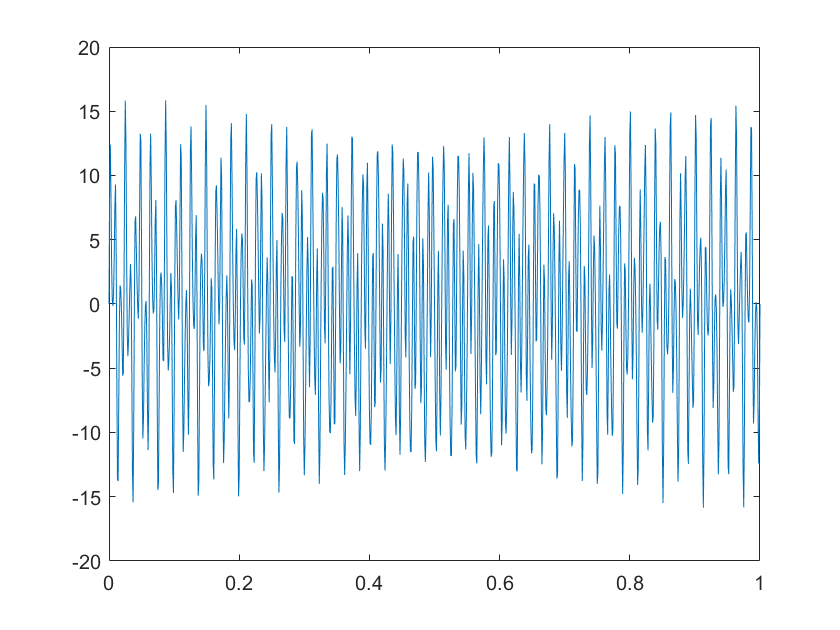

%Keitumetsi Khoza (1875831)
clear all
clc

A = 1; %first digit of your student number;
B = 8; %second digit of your student number;
C = 2; %third digit of your student number;
D = 6; %fourth digit of your student number;
E = 8; %fifth digit of your student number;
F = 2; %sixth digit of your student number;

a = 50 - A;
b = 100 + 4*B - 3*A;
c = 200 + 5*C;

Fs = 1000;
Ts = 1/Fs;
times = 0:Ts:1;


inputSignal = D*sin(2*pi*a*times) + E*sin(2*pi*b*times) + F*sin(2*pi*c*times);%+randn(size(times));
%%%%plot input
figure
plot(times, inputSignal)


%%%%%%%%%%
L = length(inputSignal);
f = Fs*(0:(L))/L;
f_ = Fs*(0:(L/2))/L;
f(1002) =[];
f_(501) =[];

X_jw =fft(inputSignal, L);
X_s = tf([157030218103271917110404109565952*pi, 0, 283071792539748445578205621530038108160*pi, 0, 48177398243081741042927025851879777074413568*pi],[39614081257132168796771975168, 0, 116146253605118413174845503268978688, 0, 67392643641751305141254205920662490447872, 0, 5378189536456462958567317625593377321600231077])

X_s =
 
         4.933e32 s^4 + 8.893e38 s^2 + 1.514e44
  -----------------------------------------------------
  3.961e28 s^6 + 1.161e35 s^4 + 6.739e40 s^2 + 5.378e45
 
Continuous-time transfer function.





%Power Spectral Density (PSD) of Input?? Not PSD but PS
P2 = abs(X_jw); % has the complex components hence, double sided
P1 = P2(1:L/2); %doubles the amplitude of the frequencies, has the real part (power spectral not PSD)

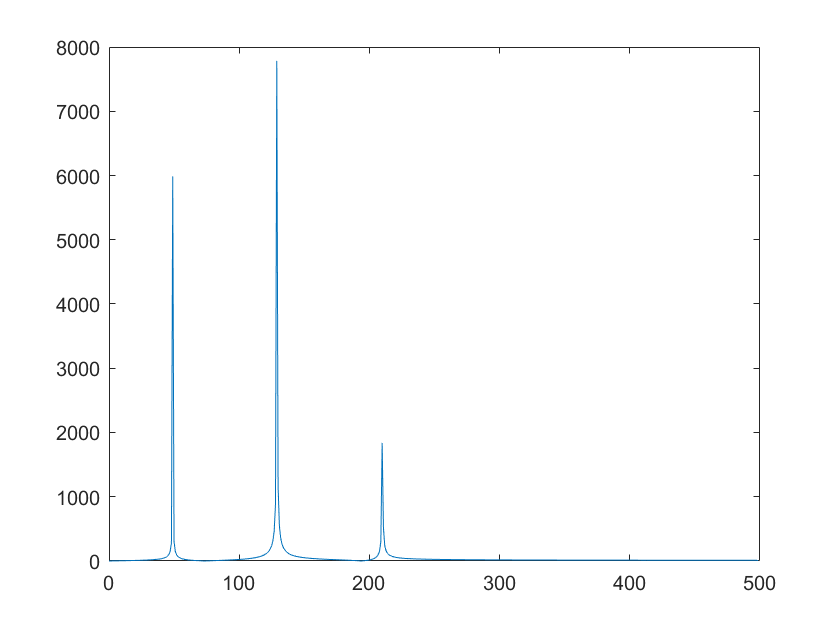

P1(2:end-1) = 2*P1(2:end-1);

figure  %Single sided
plot(f_,P1) 

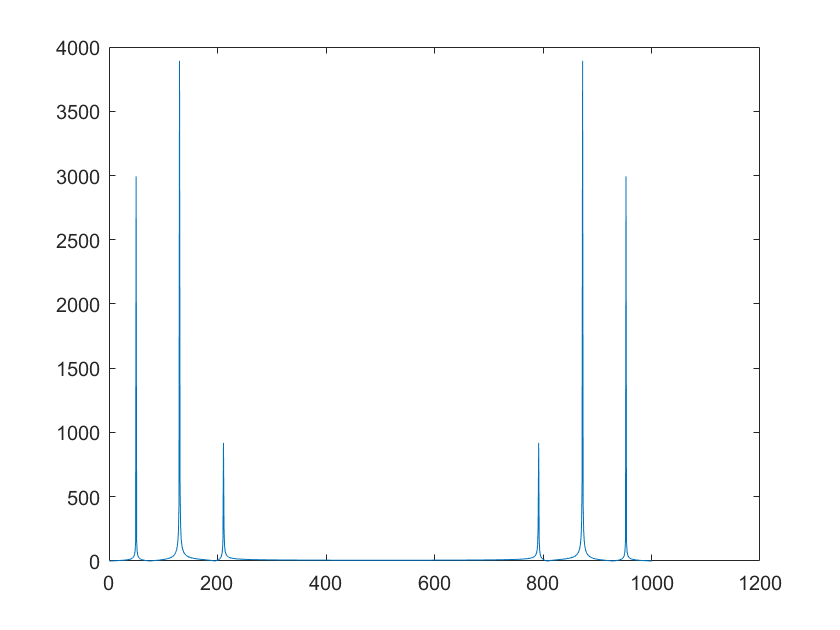


figure  %Double sided
plot(P2);

R = 50.52;
C =15e-6;

H_s = tf([1],[7.578e-4 1])

H_s =
 
         1
  ---------------
  0.0007578 s + 1
 
Continuous-time transfer function.



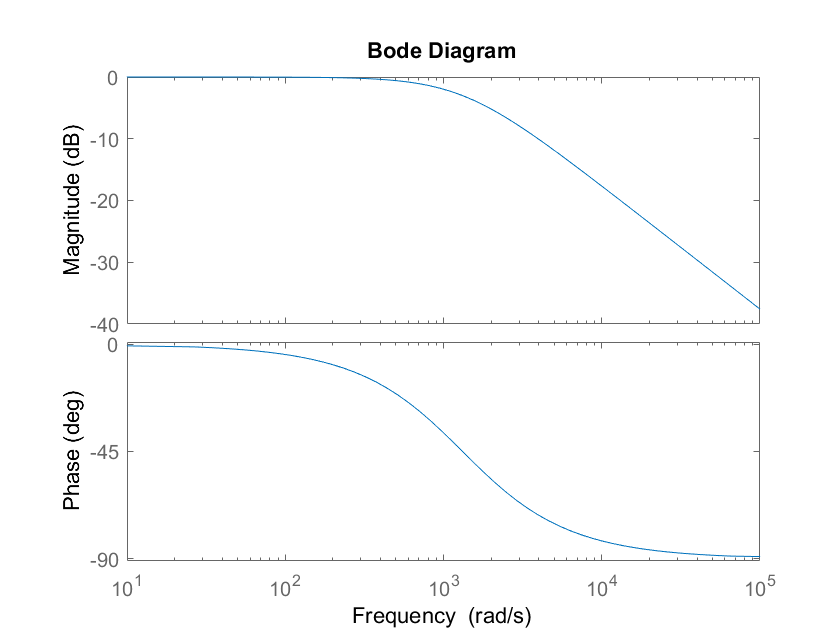

H_jw = 1./(1+R*C*2*pi*f*1i);

bode(H_s)


Y_jw = H_jw.*X_jw;
Y_s = X_s * H_s;
P2_y = abs(Y_jw);
P1_y = P2_y(1:L/2);

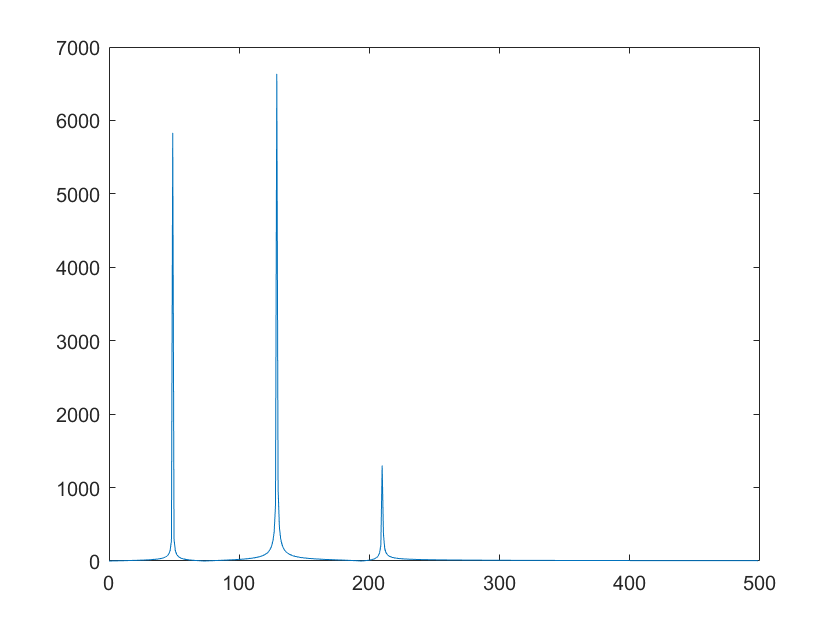

P1_y(2:end-1) = 2*P1_y(2:end-1);

figure
plot(f_,P1_y) 

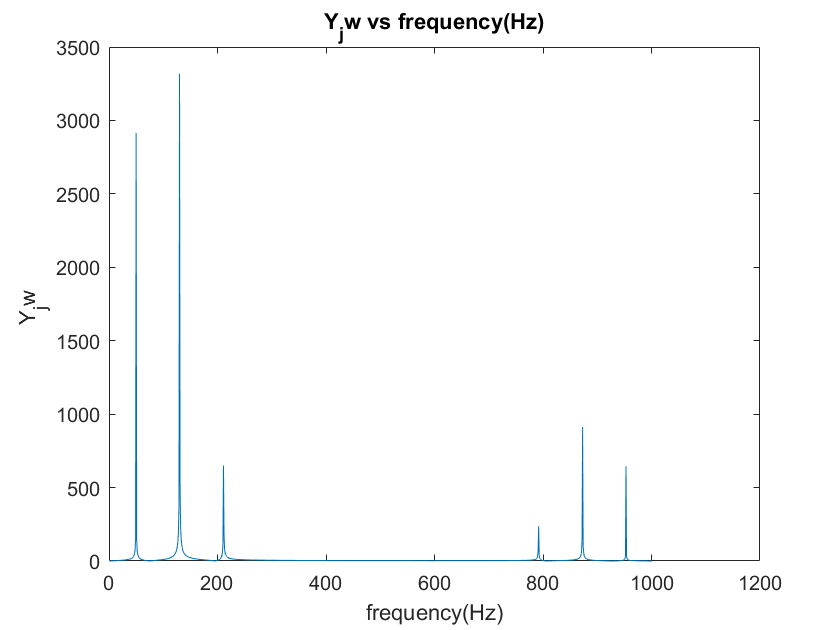



figure
plot(P2_y);
title('Y_jw vs frequency(Hz)')
xlabel('frequency(Hz)')
ylabel('Y_jw ')

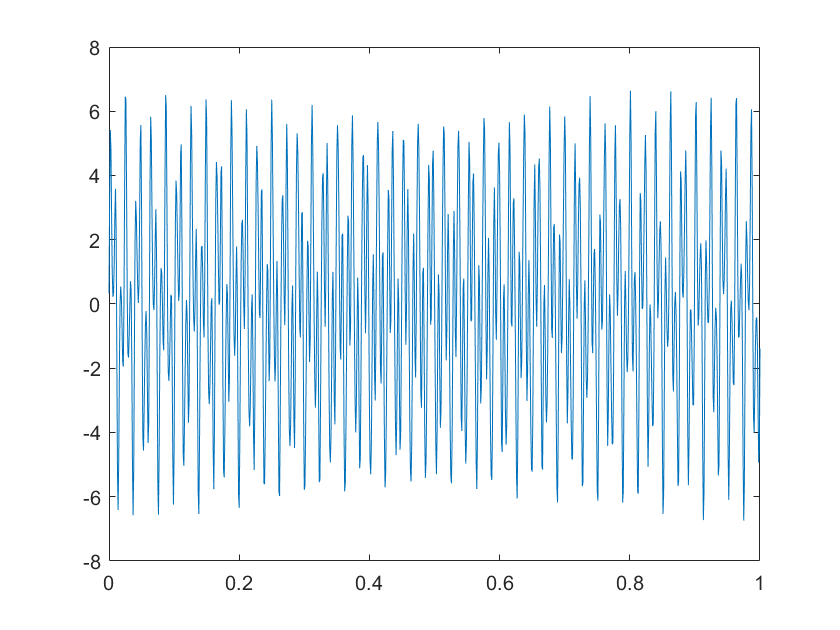


y_t = ifft(Y_jw);

figure
plot(times,y_t)